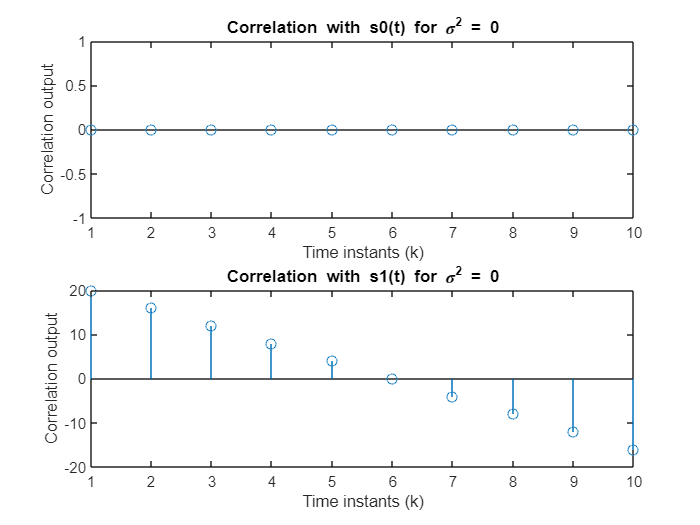

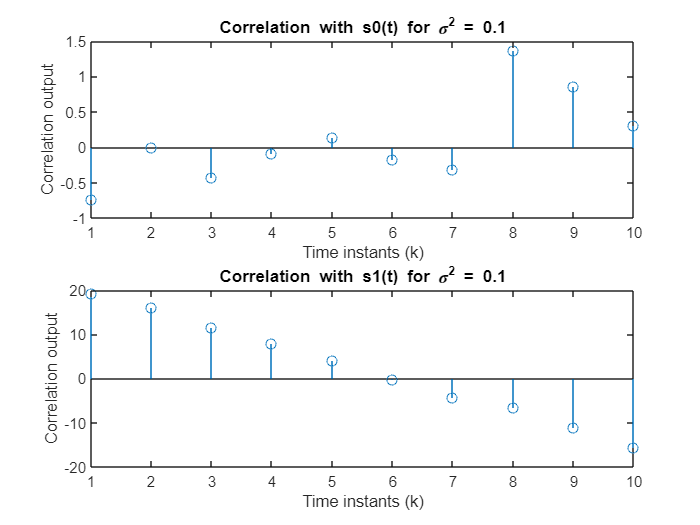

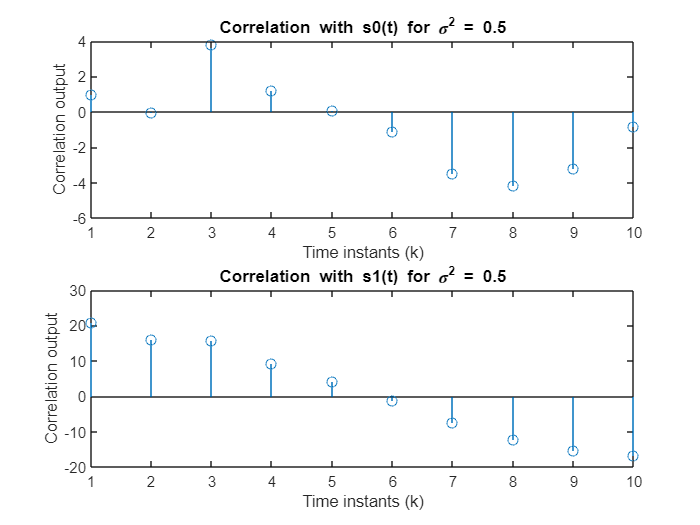

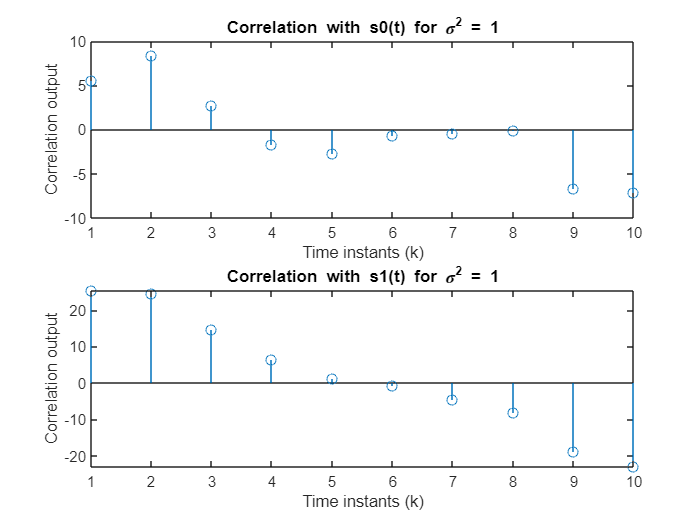

A = 1; % Amplitude
Tb = 1; % Bit interval duration
number_of_Samples = 10; % Number of samples per bit interval
sigma_squared_values = [0, 0.1, 0.5, 1.0]; % Values of noise variance
% Generate the received signal sequences for s0(t) and s1(t) for each noise variance
% for signal generation and corelation
for sigma_squared = sigma_squared_values
 % Generate the noise sequence
 nk = sqrt(sigma_squared) * randn(1, number_of_Samples * 2); % Generate Gaussian noise
 
 % Generate received signal sequence for s0(t)
 s0_samples = [A * ones(1, number_of_Samples), -A * ones(1, number_of_Samples)];
 % Sampled version of s0(t)
 received_s0 = A + nk; 
 % Received signal when s0(t) is transmitted
 
 % Generate received signal sequence for s1(t)
 s1_samples = [A * ones(1, number_of_Samples), -A * ones(1, number_of_Samples)]; % Sampled version of s1(t)
 received_s1 = [A + nk(1:number_of_Samples), -A + nk(number_of_Samples+1:end)]; % Received signal when s1(t) is transmitted
 
 % Perform correlation with s0(t)
 correlation_s0 = zeros(1, number_of_Samples);
 for k = 1:number_of_Samples
 correlation_s0(k) = sum(received_s0 .* circshift(s0_samples, [0, k-1]));
 end
 
 % Perform correlation with s1(t)
 correlation_s1 = zeros(1, number_of_Samples);
 for k = 1:number_of_Samples
 correlation_s1(k) = sum(received_s1 .* circshift(s1_samples, [0, k-1]));
 end
 
 % Plot correlator outputs for s0(t) and s1(t) at time instants k = 1, 2, 3, ..., 10
 figure;
 subplot(2, 1, 1);
 stem(1:number_of_Samples, correlation_s0);
 title(['Correlation with s0(t) for \sigma^2 = ' num2str(sigma_squared)]);
 xlabel('Time instants (k)');
 ylabel('Correlation output');
 
 subplot(2, 1, 2);
 stem(1:number_of_Samples, correlation_s1);
 title(['Correlation with s1(t) for \sigma^2 = ' num2str(sigma_squared)]);
 xlabel('Time instants (k)');
 ylabel('Correlation output');
end